## Cold plate requirements and operating conditions

The cold plate has to carry away a heat load of a maximum of 2kW. The working fluid is water. The desired maximum temperature at the cooling plate inlet is 25°C and the outlet temperature should not exceed 20°C. The coolant loop is assumed to operate at a pressure of 2 bar. The device temperature should not exceed 50°C. 

#### Operating conditions

QDiss           = simscape.Value(2000, 'W');         % Heat load
deltaTCoolant   = simscape.Value(5, 'deltadegC');    % Maximum temperature rise allowed
TCoolantIn      = simscape.Value(25, 'degC');        % Assumed coolant inlet temperature
TCoolantOutMax  = simscape.Value(30, 'degC');        % Maximum coolant outlet temperature
TSurfaceMax     = simscape.Value(50, 'degC');        % Maximum device temperature
pLoop           = simscape.Value(2, 'bar');          % Pressure in coolant loop

#### Water properties at 25°C

cpCoolant       = simscape.Value(4180.74, 'J/(kg*K)');      % Coolant heat capacity
rhoCoolant      = simscape.Value(997.137, 'kg/m^3');        % Coolant density
muCoolant       = simscape.Value(8.89995e-4, 'Pa*s');       % Coolant dynamic Pa·s
kCoolant        = simscape.Value(0.607, 'W/(m*K)');         % Coolant thermal conductivity 
PrCoolant       = simscape.Value(6.134, '1');               % Coolant Prandtl number

#### Required flow rate

The required steady-state flow rate to keep the outlet temperature at a maximum of 30°C with the assumed inlet temperature is determined using:


$$Q_{\textrm{Diss}} =\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{cp},\textrm{in}} \right)*{\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$


mDot    = QDiss/(cpCoolant*deltaTCoolant); % Coolant mass flow rate
VDot    = mDot/rhoCoolant;                 % Coolant volumetric flow rate

#### Testing in a Simscape model

To test this in a simulation a simple model is build

open_system("example_TCoolantOut")

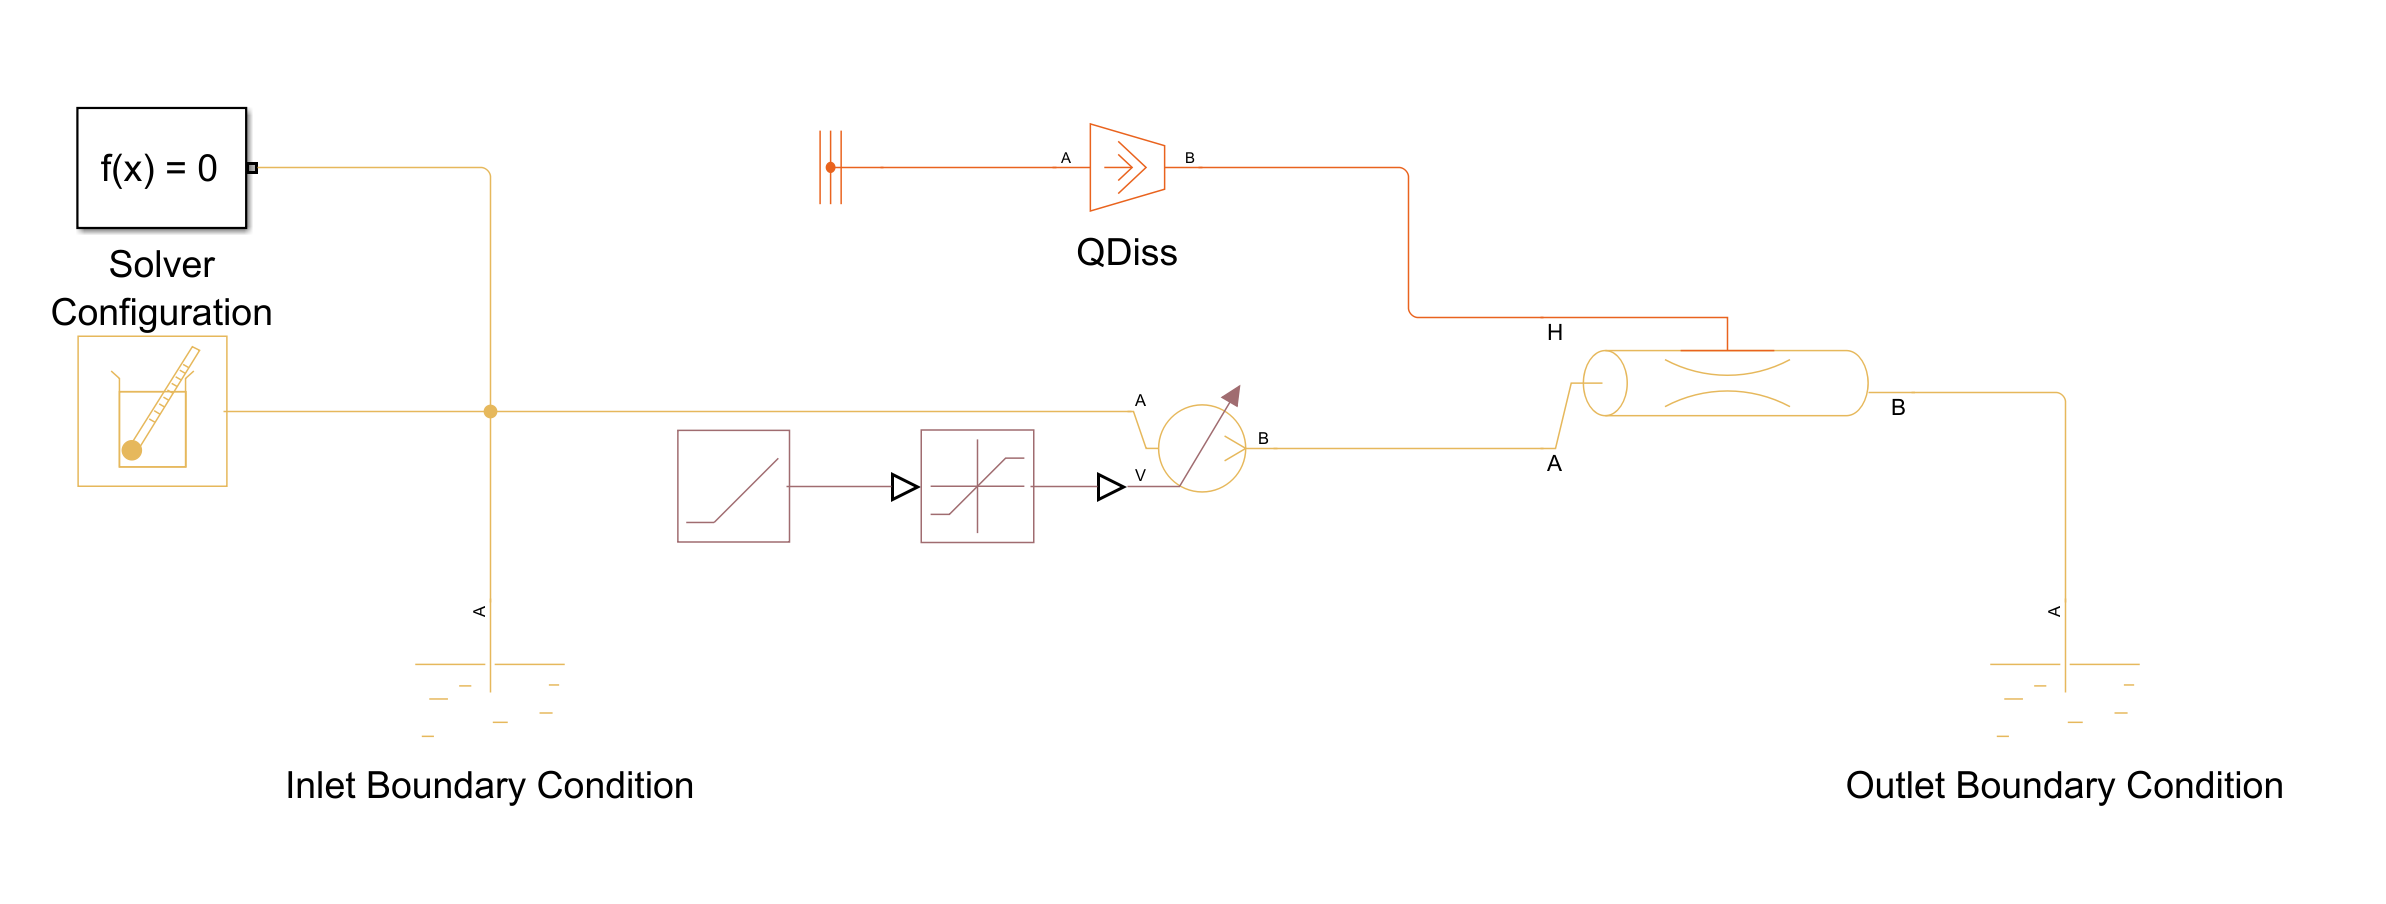

Two Reservoirs act as as inlet and outlet boundary conditions. Since we are only looking at results after the simulation has reached steady-state and are at this point not looking at pressure losses, we leave the pipe geometry parameters at the default values. The flow rate is created using a Flow Rate Source, we are starting from resting fluid and ramping up to the desired flow rate. We leave the model running for a long enough simulation time to reach steady state. An look at the result at the final result.

simInp = Simulink.SimulationInput("example_TCoolantOut");
simInp = simInp.setModelParameter("StopTime","7200");

simOut = sim(simInp);

Next, we'll extract resuts from the Simscape logging object. For the pipe block we can extract values for the ports (**A** and **B**) and since the block also has a internal fluid volume the node **T_I** will also be visible in the Simscape logging object. In the example we imposed a positive flow rate, meaning the flow will go from port A to port B in the pipe, therefore the temperature at port B will be the same as at port T_I. This is due to the [Upwinding Numerical Scheme](https://www.mathworks.com/help/releases/R2025a/hydro/ug/simscape-fluids-numerical-scheme.html) which is used in Simscape domains to carry along energy, species flows, etc. along with the mass flow. 

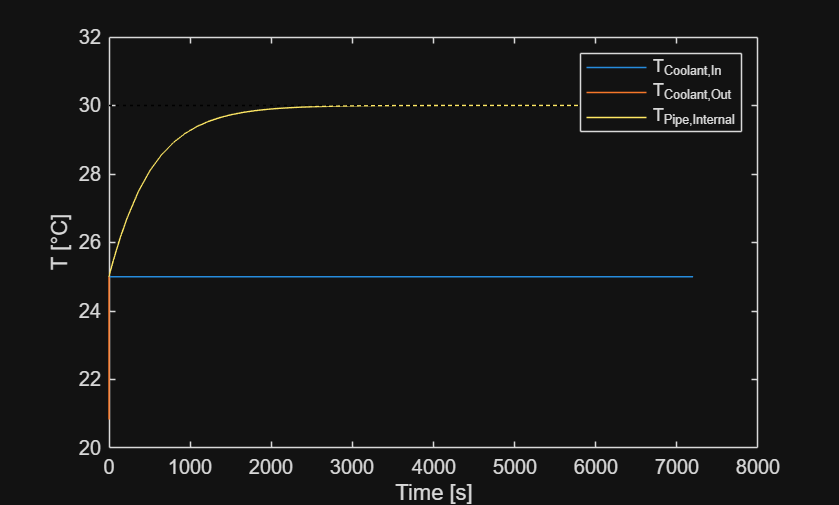

TPipeA = simOut.simlog.Pipe_TL.A.T.series.values('degC');
TPipeB = simOut.simlog.Pipe_TL.B.T.series.values('degC');
TPipeT_I = simOut.simlog.Pipe_TL.T_I.series.values('degC');

figure
plot(simOut.tout,[TPipeA,TPipeB,TPipeT_I])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax.value('degC'),TCoolantOutMax.value('degC')],'k:')
ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,In}','T_{Coolant,Out}','T_{Pipe,Internal}')
hold off

We can verify that the outlet temperature converges to the desired maximum outlet temperature and that the internal node value is consistent with the outlet node (**B**) temperature. 

#### Required thermal resistance for the required maximum device temperature

Next we will look at the necessary resistance that would ensure the device stays at its maximum allowed temperature of 50°C. For steady state the surface temperatute can be determined using


$$T_{\textrm{surface}} =Q_{\textrm{Diss}} *R_{\textrm{CP}} \;+T_{\textrm{cp},\textrm{out}}$$


Rcp = simscape.Value(TSurfaceMax.value('degC') - TCoolantOutMax.value('degC'),'deltadegC')/QDiss;  
disp(Rcp)

    0.0100 (deltadegC/W)



#### Testing in a Simscape model

We can replicate this in a Simscape model. 

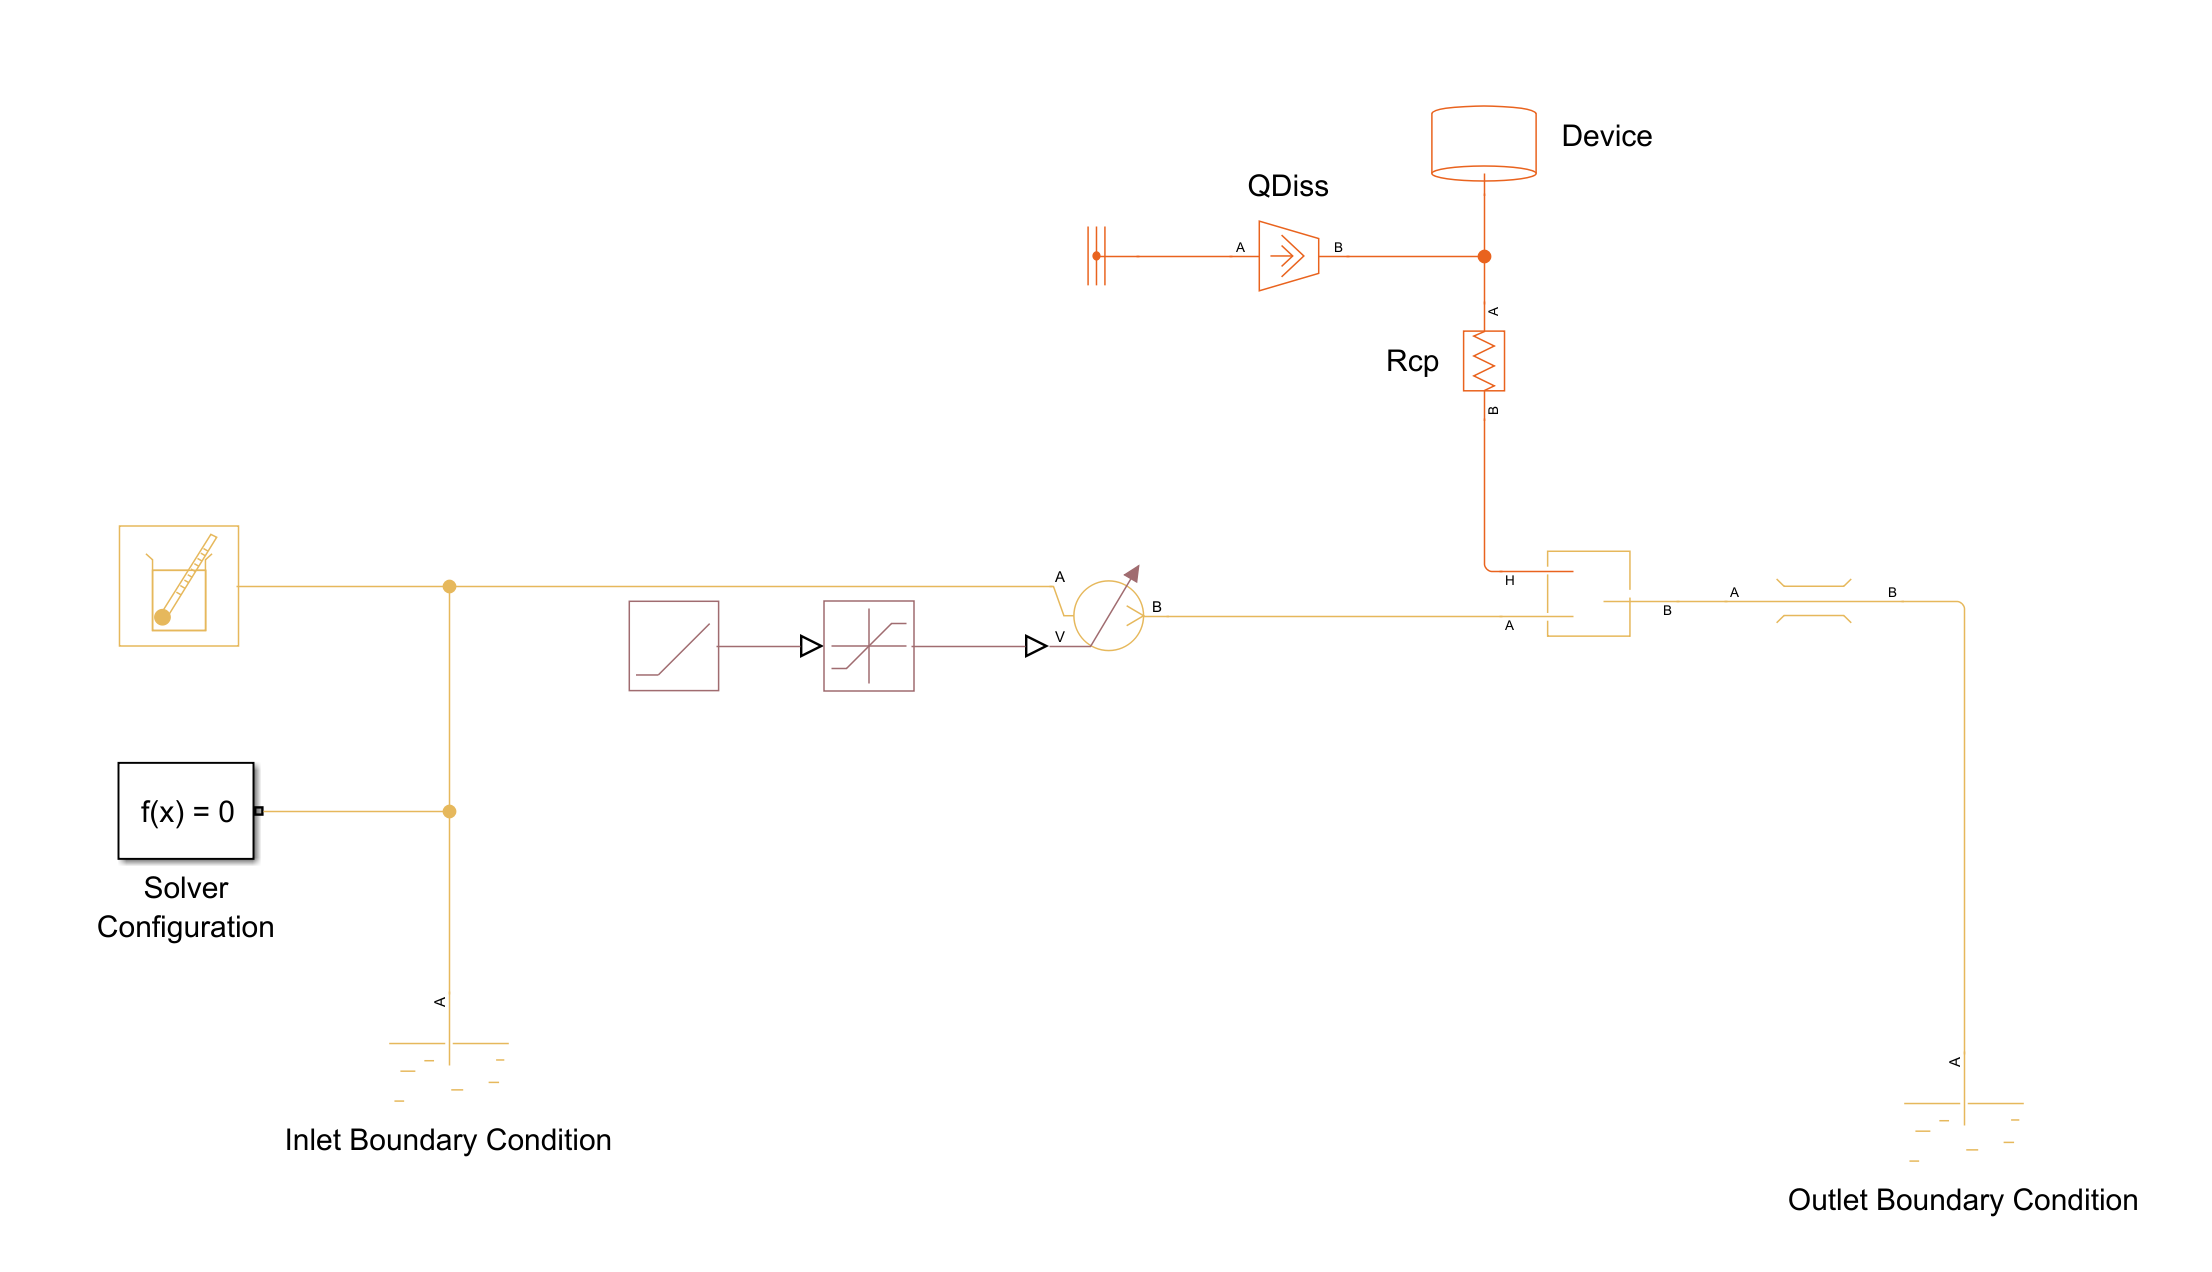

The cold plate fluid volume is here represented using a Constant Volume Chamber TL. In contrast to the Pipe TL block the thermal H port is directly connected to the internal fluid node, and there is no thermal resistance present. The Pipe TL block calculates convective heat transfer between its H port and the internal fluid volume. So to be able to test the overall thermal resistance value from convection and conduction, a Constant Volume Chamber TL block is used. Simlarly, since there is no resistance between internal node and A and B port, therefore a Flow Resistance is added, to disconnect the internal node from the outlet boundary condition. (Link example Pipe vs. Chamber here??)

open_system("example_Rcp_Chamber")

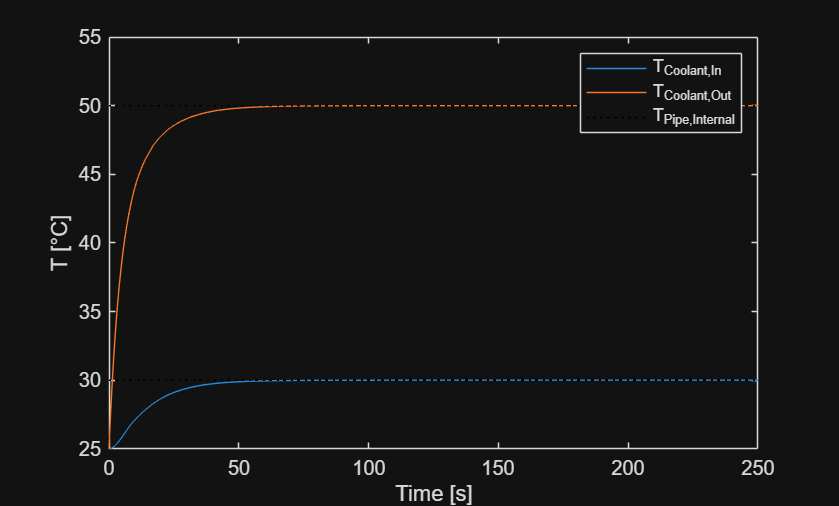

simInp = Simulink.SimulationInput("example_Rcp_Chamber");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TChamberOut = simOut.simlog.Constant_Volume_Chamber_TL.B.T.series.values('degC');
TDevice     = simOut.simlog.Device.M.T.series.values('degC');

figure
plot(simOut.tout,[TChamberOut,TDevice])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax.value('degC'),TCoolantOutMax.value('degC')],'k:')
plot([simOut.tout(1),simOut.tout(end)],[TSurfaceMax.value('degC'),TSurfaceMax.value('degC')],'k:')

ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,In}','T_{Coolant,Out}','T_{Pipe,Internal}')
hold off

We can see the both the device temperature and the outlet temperature to reach both their maximum allowed values, confirming, the determined thermal resistance. 

#### Sizing the cold plate 

In a seperate script we evaluate a U-shaped channel cold plate configuration vs. a parallel channels configuration for different geometric parameters. To see this in more detail investigate and run

    [Cold Plate Parameterization](matlab:open('.\ColdPlateParameterization.mlx'))

Here, we will continue with the final choice of a parallel channel configuration:

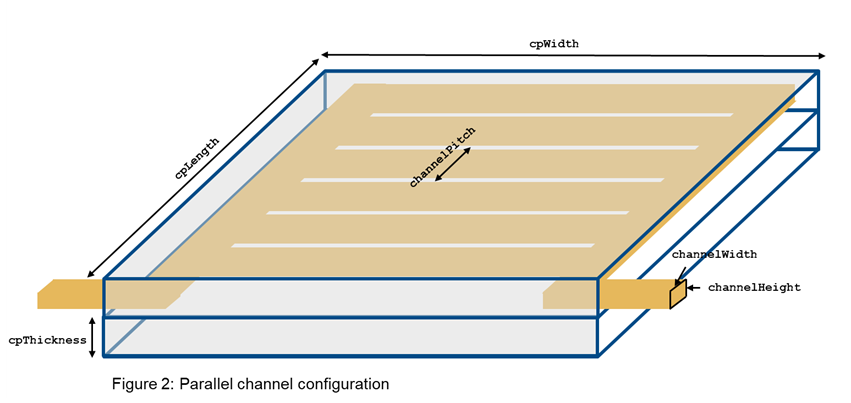

The parameters selected (based on [Cold Plate Parameterization](matlab:open('.\ColdPlateParameterization.mlx'))) are:

cpLength            = simscape.Value(320, 'mm');    
cpWidth             = simscape.Value(320, 'mm');     
channelWidth        = simscape.Value(2, 'mm');       
channelHeight       = simscape.Value(8, 'mm');       
channelMargin       = simscape.Value( 10, 'mm'); 
channelRoughness    = simscape.Value( 1e-5, 'm'); 
cpThickness         = simscape.Value(5, 'mm');  
deviceD             = simscape.Value(75, 'mm');
cpK                 = simscape.Value(167, 'W/(m*K)');

For both the parallel channels configuration, we will use a [Pipe (TL)](https://www.mathworks.com/help/releases/R2025b/simscape/ref/pipetl.html?s_tid=doc_ta) to represent the geometry. Assuming, that the flow is split evenly between all flow channels, we can only model one channel to represent the entire geometry. For this purpose, we will use an additional custom library containing "flow splitters":

open_system(projRoot + "\Libraries\supplemental_lib.slx")

The flow splitters acts as a multiplier or divider, to make sure in the thermal liquid domain, the flow is divided at the pipe input/and multiplied at outpur. Similarily, the splitter in the thermal domain, will multiply or divide the heat flow rate. Using this approach will result in a smaller and more performant model and is valid under the assumptions we made. 

Additionally we will calculate derived parameters, this includes the device surface area, the number of parallel channels, as well as an equivalent length parameter. The latter is used to account for additional pressure drops from the cold plate, the component Pipe (TL) calculates the pressure drop due to viscous friction for the given geometry and conditions, additional pressure losses can be accounted for, using the equivalent length parameters. The Pipe (TL) block uses a Haaland approximation to calculate the Darcy friction factor for turbulent flow. For laminar flow, it uses a constant shape factor. The parameter Aggregate equivalent length of local resistances, can be used to account for additional resistances for example due to bends, resistances and other pipe fittings. We use an equivalent lenght parameter to account for the additional bends at channel inlet and outlet.  

cpDeviceSurfaceArea   = pi*(deviceD/2)^2; 
channelArea           = channelHeight*channelWidth;                                % Channel cross-sectional area
channelDh             = 2*channelWidth*channelHeight/(channelHeight+channelWidth); % Channel hydraulic diameter

channelLength         = cpWidth - 2*channelMargin;                                 % Flow length per each channel
numChannels           = floor((cpLength - 2*channelMargin)/channelPitch);          % Number of parallel channels
numBend               = 2;                                                         % Number of 90 degree bends per parallel channel 
equivalentLength      = numBend*60*channelDh;                                      % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow

open_system("example_ColdPlate")

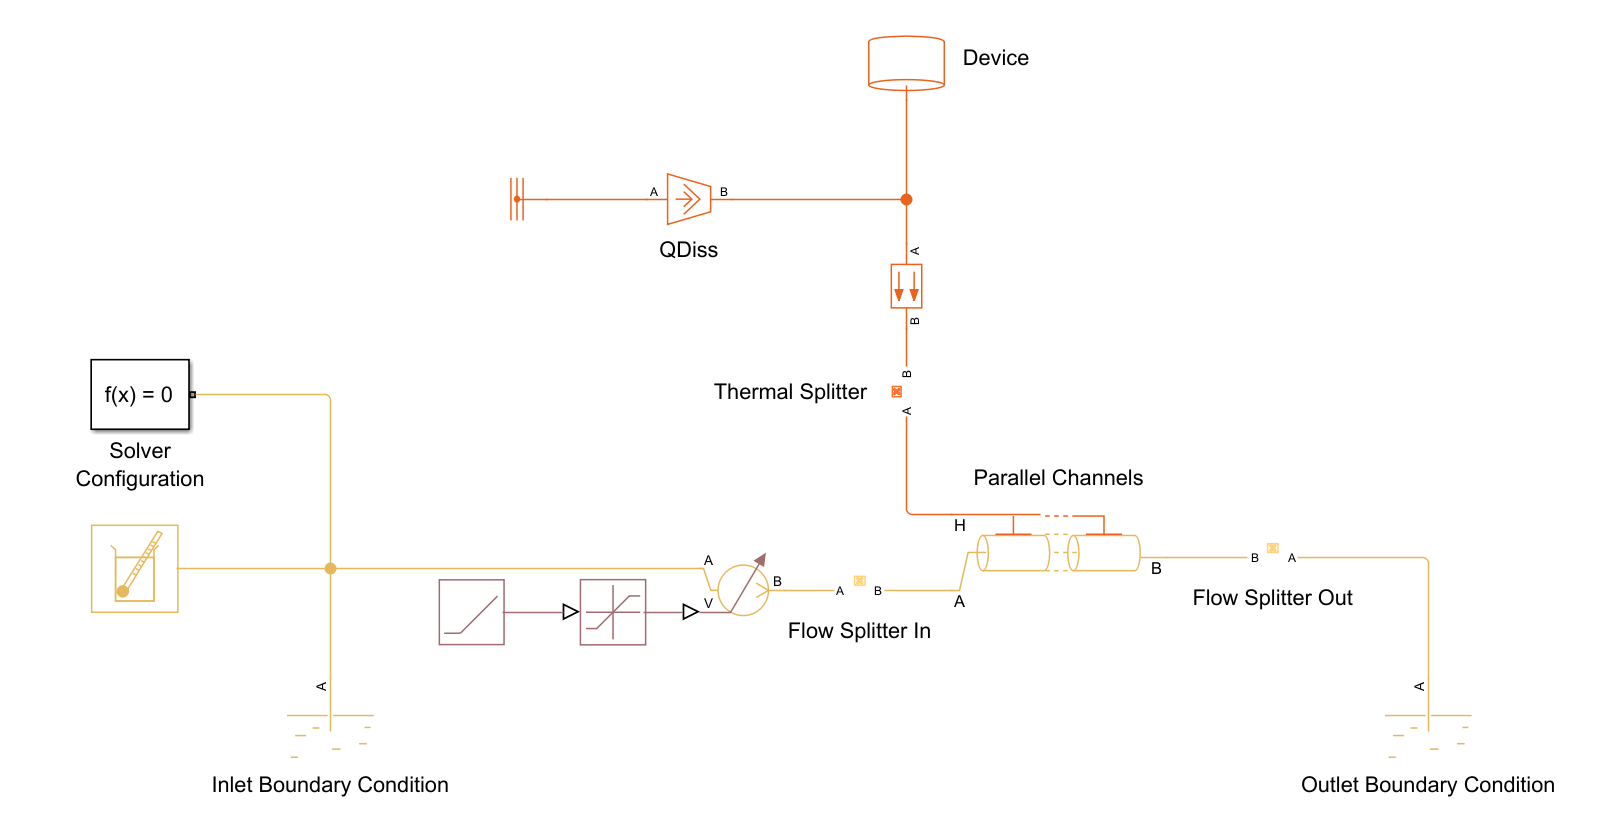

With the given values we simulate the and extract the coolant outlet and device temperature, additionally we calculate the resulting overall thermal resistance for this cold plate setup. 

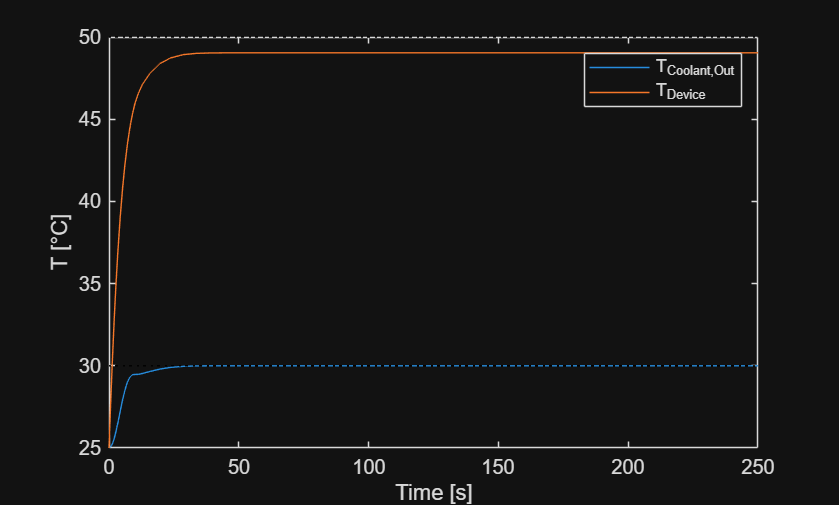

simInp = Simulink.SimulationInput("example_ColdPlate");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TColdPlateOut = simOut.simlog.Parallel_Channels.B.T.series.values('degC');
TDevice       = simOut.simlog.Device.M.T.series.values('degC');

figure
plot(simOut.tout,[TColdPlateOut,TDevice])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax.value('degC'),TCoolantOutMax.value('degC')],'k:')
plot([simOut.tout(1),simOut.tout(end)],[TSurfaceMax.value('degC'),TSurfaceMax.value('degC')],'k:')

ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,Out}','T_{Device}')
hold off


TColdPlate_I = simOut.simlog.Parallel_Channels.segment.T_I.series.values('degC');
deltaT = TDevice-TColdPlate_I;
RcpSim = simscape.Value(deltaT(end), 'deltadegC')/QDiss;
disp(RcpSim)

    0.0095 (deltadegC/W)



The results show, that I am staying within the given ranges, accordingly the thermal resistiance is a little below the desired value. 

#### Cold plate pressure drop

In the next step, we will size the pump for the cooling system, the cold plate will contribute significantly to the overall pressure drop. We will extract the values from the results:

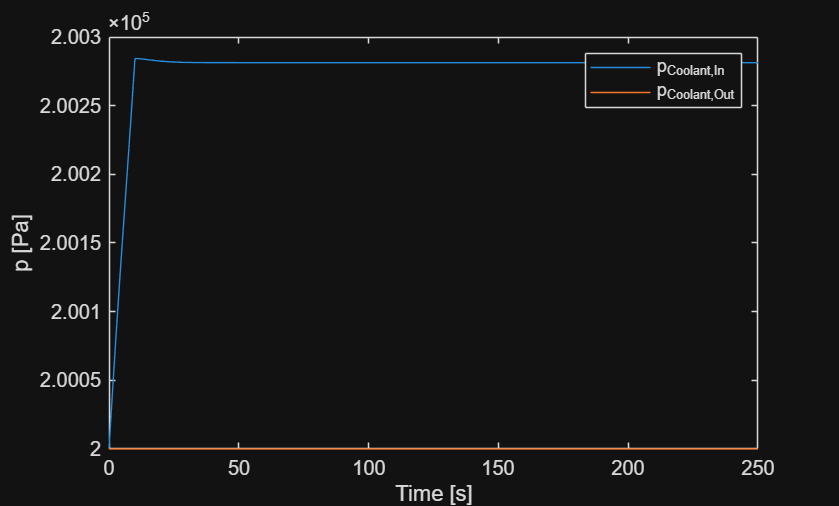

pColdPlateIn    = simOut.simlog.Parallel_Channels.A.p.series.values('Pa');
pColdPlateOut   = simOut.simlog.Parallel_Channels.B.p.series.values('Pa');

dpColdPlate     = pColdPlateIn-pColdPlateOut;

figure
plot(simOut.tout,[pColdPlateIn,pColdPlateOut])
ylabel('p [Pa]')
xlabel('Time [s]')
legend('p_{Coolant,In}','p_{Coolant,Out}')
hold off


disp(dpColdPlate(end))

  281.3629



At steady state for the maximum flow rate, the current cold plate design produces a pressure drop of roughly 0.003 bar. 